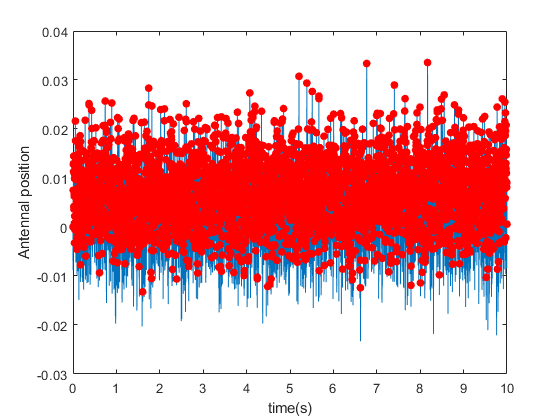

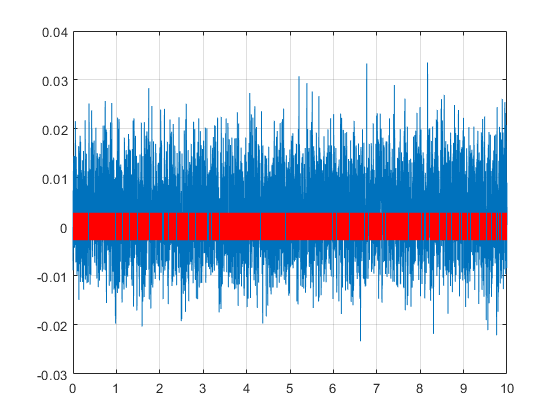

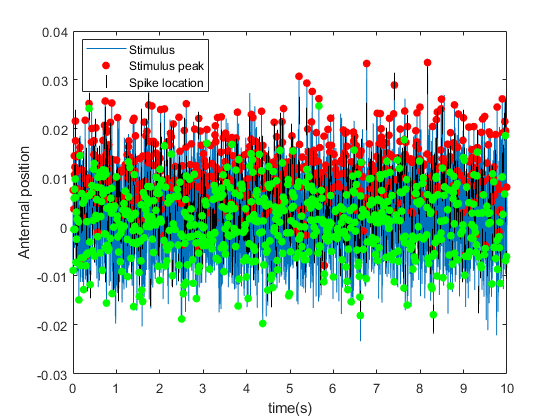


stim = P(2).antennal_movement(:,start_stim:stop_stim);
diff_stim =((stim-stim(1,1)));
raster = P(2).raster(:,start_stim:stop_stim);


stim_level = NaN(no_of_trials,length(stim));
stim_locs = NaN(no_of_trials, length(stim));
spike_stim_peak_locs = [];% NaN(no_of_trials, length(stim));
spike_stim_trough_locs = [];
latency_to_peak = [];%NaN(no_of_trials, length(stim));
latency_to_trough = [];
position_change = [];
velocity = [];


t = 0:1/fs:ON_dur;


for j=1 %:no_of_trials
    
    spike_locs = find(raster(j,:));
    [pks, peak_locs] = findpeaks(diff_stim(j,:));
    
    [troughs, trough_locs] = findpeaks(-diff_stim(j,:));
    
    figure;
    plot(t, diff_stim(j,:), peak_locs/fs, pks, 'r.', 'MarkerSize', 20);
    xlabel('time(s)')
    ylabel('Antennal position')
    
    figure;
    plot(t,diff_stim(1,:),spike_locs/fs,0, 'r|', "MarkerSize", 20); grid on;
    
    
    for k=1:numel(spike_locs)
        
        stim_level(j,k)  = diff_stim(j,spike_locs(k));
        stim_locs(j,k) = (spike_locs(k))/fs;
        %             min(spike_locs(k)-locs)
        %             [spike_stim_val(j,k),spike_stim_locs(j,k)] = min(spike_locs(k)-locs(1:spike_locs(k)));
        spike_stim_peak_locs(j,k) = peak_locs(find(peak_locs<spike_locs(k), 1, 'last'));
        spike_stim_trough_locs(j,k) = trough_locs(find(trough_locs<spike_locs(k), 1, 'last'));
        
        latency_to_peak(j,k) = spike_locs(j,k) - spike_stim_peak_locs(j,k);
        latency_to_trough(j,k) = spike_locs(j,k) - spike_stim_trough_locs(j,k);
        
        position_change(j,k) = diff_stim(j,spike_stim_peak_locs(j,k))- diff_stim(j,spike_stim_trough_locs(j,k));
        velocity(j,k) = (position_change(j,k)*fs)/(spike_stim_peak_locs(j,k)-spike_stim_trough_locs(j,k));
        
    end
    
    %         ind_ind = randperm(length(spike_locs),10);
    %         ind = spike_locs(ind_ind);
    %
    %         figure;
    %         plot(t, diff_stim(j,:), spike_stim_locs(j,ind_ind)/fs, diff_stim(j,spike_stim_locs(ind_ind)), 'r.', ind/fs, diff_stim(j,ind), 'k.', 'MarkerSize', 20)
    %     figure;
    %         plot(t,diff_stim(j,:)); hold on;
    %         diff_stim = [nan diff(diff_stim(j,:))];
    %         plot(t,diff_stim(j,:)); hold on;
    figure;
    plot(t, diff_stim(j,:), spike_stim_peak_locs/fs, diff_stim(j,spike_stim_peak_locs), 'r.', spike_locs/fs, diff_stim(j,spike_locs), 'k|', spike_stim_trough_locs/fs, diff_stim(j,spike_stim_trough_locs), 'g.', 'MarkerSize', 20);
%     hold on; plot(); hold off;
    xlabel('time(s)')
    ylabel('Antennal position')
    legend('Stimulus', 'Stimulus peak', 'Spike location', 'Location',"best");
    %         plot(stim_locs(j,:),stim_level(j,:), 'r.');
    %         plot(stim_locs(j,:),stim_level(j,:), 'r.');
    
    
end

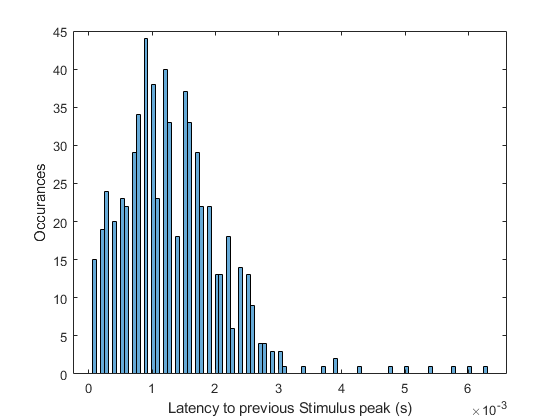


figure;
histogram(latency_to_peak/fs, 100);
ylabel('Occurances');
xlabel('Latency to previous Stimulus peak (s)')

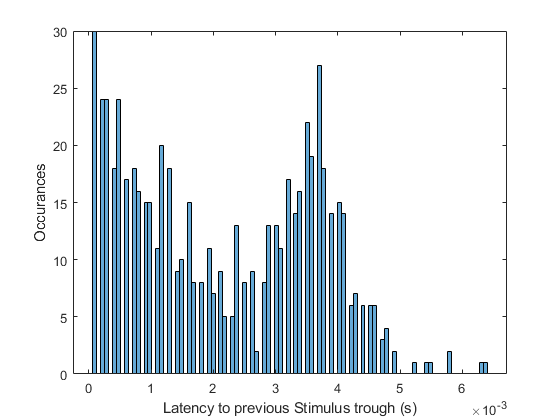


figure;
histogram(latency_to_trough/fs, 100);
ylabel('Occurances');
xlabel('Latency to previous Stimulus trough (s)')

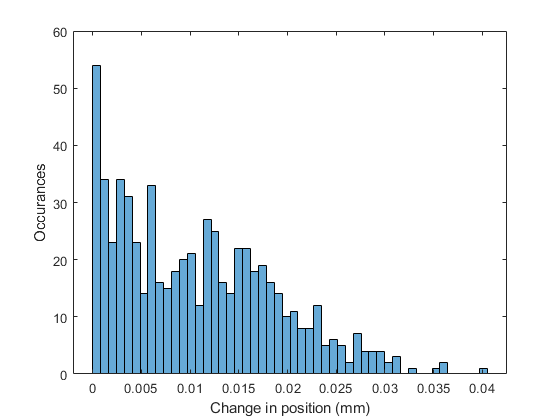


figure;
histogram(position_change, 50);
ylabel('Occurances');
xlabel('Change in position (mm)')

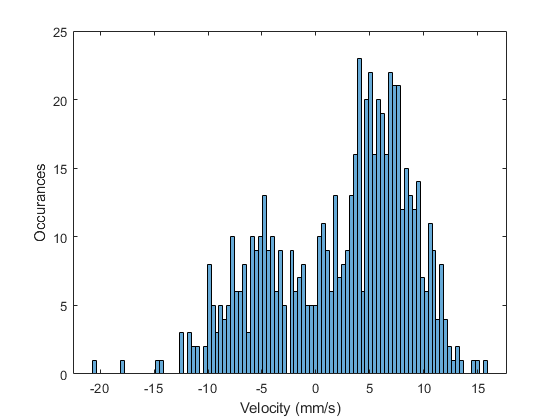


figure;
histogram(velocity, 100);
ylabel('Occurances');
xlabel('Velocity (mm/s)')

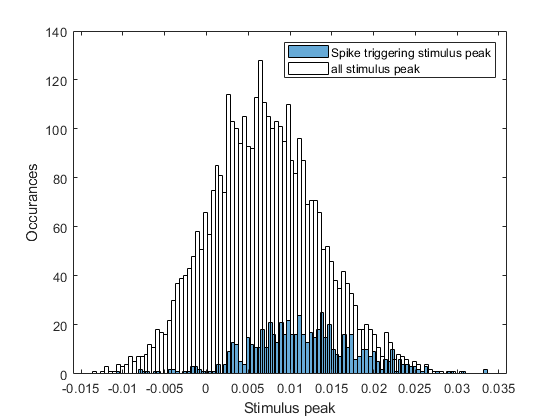


figure;
histogram(diff_stim(j,spike_stim_peak_locs),100); hold on;
histogram(diff_stim(j, peak_locs), 100, "FaceColor","none");
ylabel('Occurances');
xlabel('Stimulus peak');
legend('Spike triggering stimulus peak', 'all stimulus peak');

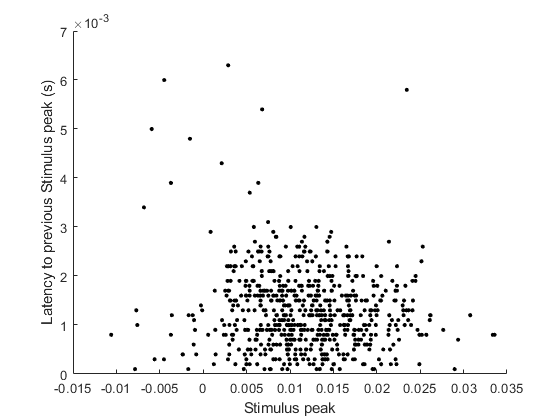


stim_val = diff_stim(j,spike_stim_peak_locs);
figure;
scatter(diff_stim(j,spike_stim_peak_locs), latency_to_peak/fs, 10, "black", 'filled')
ylabel('Latency to previous Stimulus peak (s)')
xlabel('Stimulus peak');

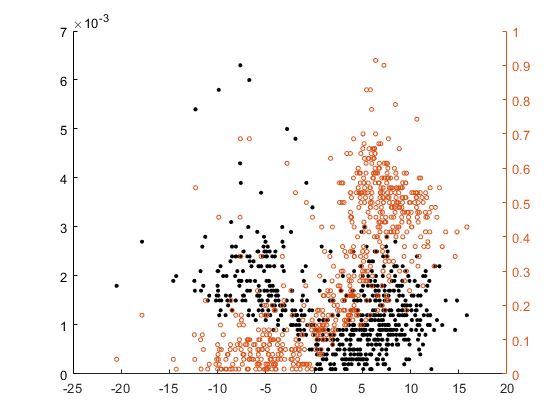


figure;
scatter(velocity, latency_to_peak/fs, 10, "black","filled"); yyaxis left; hold on;
scatter(velocity, latency_to_trough/fs, 10, [0.8500 0.3250 0.0980]); yyaxis right;